# Constants

global x1; global x2; global x3;global x4;
global a1;global a2;global a3;
x1 = 1;
x2 = 1;
x3 = 1;
x4 = 1;

a1 = 1;
a2 = -1;
a3 = 1;

global N; global sig;
N = 100

N = 100

sig = 0.04

sig = 0.0400


niter=1000; % number of experiments for avg values

# Functions definition

dhdx=@dhdxdef;
% calman H
ht=@htdef;
angle=@angledef;
calmanmy=@calmandef;

# Cramer-Rao

NCramer=[5 20 100]; %different values of N
sigCramer=[0.2 0.04];%different values of sigma
[Ni,sigmai] = ndgrid(NCramer,sigCramer);
V=[Ni(:),sigmai(:)];

for iter = 1 : size(V,1)
    Ni=V(iter,1);
    sigi=V(iter,2);

    H = zeros(Ni,4);
    for T = 1:Ni
        %     take less value for t(i+1)-t(i)
        t = T/10;
        for k = 1:4
            H(T,k) = dhdx(t,k);
        end
    end

    F = H'*H/sigi^2;
    D = trace(inv(F));
    fprintf('Dispersion (Kramer-Rao edge) for N=%d sigma=%.2f : %.4f\n',V(iter,1),V(iter,2),D)
end

Dispersion (Kramer-Rao edge) for N=5 sigma=0.20 : 19056.6526
Dispersion (Kramer-Rao edge) for N=20 sigma=0.20 : 3.3762
Dispersion (Kramer-Rao edge) for N=100 sigma=0.20 : 0.4863
Dispersion (Kramer-Rao edge) for N=5 sigma=0.04 : 762.2661
Dispersion (Kramer-Rao edge) for N=20 sigma=0.04 : 0.1350
Dispersion (Kramer-Rao edge) for N=100 sigma=0.04 : 0.0195


# Last squares method+Calman filter

xlsqr = zeros(niter, 4);
xcalman = zeros(niter, 4);

for k = 1:niter
    %     random noise with dispersion=sig
    da = sig*randn([N 1]) ;
    A = zeros(N, 4);
    b = zeros(N,1);

    for l = 1:N
        t = l/10;
        %         take noise(l) but take angle(l/10)
        mult = (sin(angle(t)+ da(l)))^2/t;
        A(l,1) = t;
        A(l,2) = -t*cot(angle(t)+ da(l));
        A(l,3) = 1;
        A(l,4) = -cot(angle(t)+ da(l));
        A(l,:)=mult*A(l,:);

        b(l) = (a1*t^2+a2*t+a3)*mult;

    end
    %     calc vector X by last squares method
    xlsqr(k,:) = A\b;
    %     calc vector X by calman filter
    xcalman(k,:) = calmanmy(da);
end

# Avg

[stdLSM,meanLSM] = std(xlsqr)

stdLSM =     0.0319    0.0495    0.0610    0.1565


meanLSM =     0.9949    1.0601    0.9825    0.8971


[stdCalman,meanCalman] = std(xcalman)

stdCalman =     0.0319    0.0494    0.0610    0.1566


meanCalman =     0.9949    1.0597    0.9828    0.8985


dispLSM=diag(cov(xlsqr))'

dispLSM =     0.0010    0.0024    0.0037    0.0245


dispCalman=diag(cov(xcalman))'

dispCalman =     0.0010    0.0024    0.0037    0.0245


# Plotting

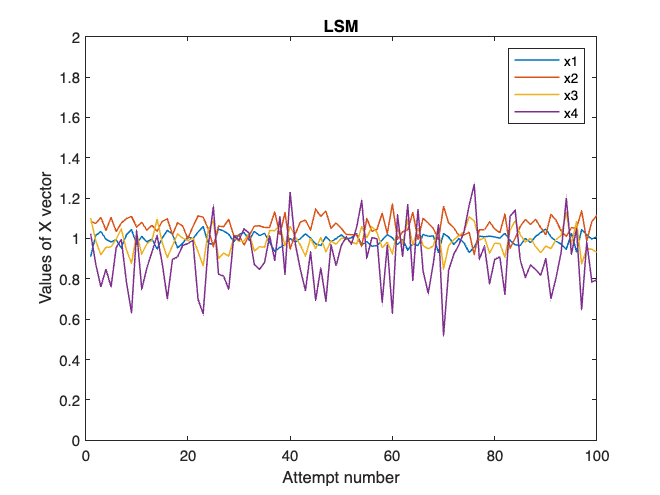

plot(xlsqr(1:100,:),LineWidth=1);xlim([0 100]);ylim([0 2]);
xlabel("Attempt number"); ylabel("Values of X vector");
legend('x1','x2','x3','x4');title("LSM");

hold on;

hold off;

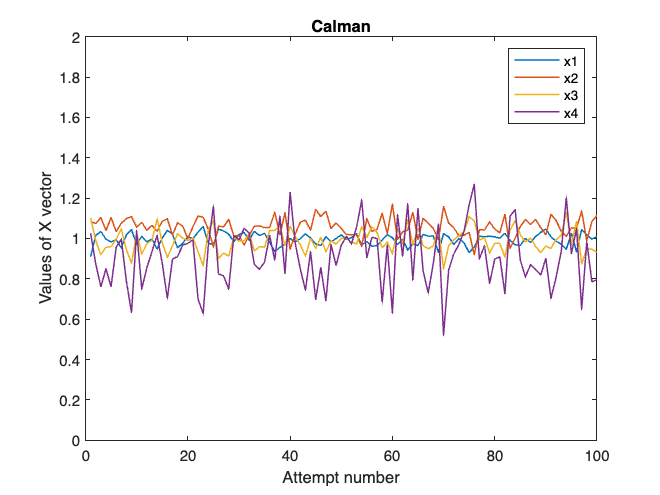

plot(xcalman(1:100,:),LineWidth=1);xlim([0 100]);ylim([0 2]);
xlabel("Attempt number"); ylabel("Values of X vector");
legend('x1','x2','x3','x4');title("Calman");
hold on;
hold off;

# Function defining

function ret = dhdxdef (t, k)
    global x1; global x2; global x3;global x4;
    global a1;global a2;global a3;
    
    fractiondef=(x1*t+x3-a1*t^2-a2*t-a3)/(x2*t+x4);
    
    koef=-1/(1+fractiondef^2)/(x2*t+x4);
    
    dhdx = koef*[t -t*fractiondef 1 -fractiondef];
    
    ret=dhdx(k);
end

% retrurn angle
function ret = angledef (t)
    global x1; global x2; global x3;global x4;
    global a1;global a2;global a3; 
%     acot2(x,y)=atan2(y,x)
    ret = atan2(x2*t+x4,x1*t+x3-a1*t*t-a2*t-a3);
end

% retrun h
function ret = htdef (t, da)
    mult = (sin(angledef(t)+ da))^2/t;
    ret=mult*[t -t*cot(angledef(t)+ da) 1 -cot(angledef(t)+ da)];
end

% return X value after N iteration
function X0 = calmandef (da)
global sig; global N; global a1;global a2;global a3;

X0 = [2;2;2;2];
Pxx = eye(4);
for k = 1:N
    t = k/10;
    h = htdef(t, da(k));
    mult=(sin(angledef(t)+ da(k)))^2/t;
    z = (a1*t^2+a2*t+a3)*mult;
    X0 = X0 + (Pxx*h')/(h*Pxx*h'+ sig^2)*(z-h*X0);
    Pxx = Pxx - (Pxx*h')/(h*Pxx*h'+ sig^2)*h*Pxx;
end
end